init
g0 = 9.08;
m = 100000 % mass of sc

m = 100000

r1 = 1000 + Rearth % orbit 1

r1 = 7378

r2 = 36000 + Rearth % orbit 2

r2 = 42378

e = EccfromRpRa(r1,r2) % transfer orbit

e = 0.7034

a = (r1+r2)/2

a = 24878

v1_i = v1_init(Gearth,r1)

v1_i = 7.3502

v1_f = VfromRA(Gearth,r1,a)

v1_f = 9.5932

v2_i = VfromRA(Gearth,r2,a)

v2_i = 1.6702

v2_f = v2_final(Gearth,r2)

v2_f = 3.0669

dv1 = v1_f-v1_i

dv1 = 2.2430

dv2 = v2_f-v2_i

dv2 = 1.3967


dv = dv1+dv2

dv = 3.6397

TOF = PeriodfromA(Gearth,a)/2

TOF = 1.9526e+04


TOF/Hour

ans = 5.4238


% part 2
% find energy of each orbit to determine thrust requirement
E_orbit1 = EfromA(Gearth,r1)

E_orbit1 = -27.0128

E_transferorbit = EfromA(Gearth,a)

E_transferorbit = -8.0111

E_orbit2 = EfromA(Gearth,r2)

E_orbit2 = -4.7029

% energy change
E_1tot = E_transferorbit - E_orbit1

E_1tot = 19.0017

E_tto2 = E_orbit2 - E_transferorbit

E_tto2 = 3.3082


deltaE_tot = E_orbit2-E_orbit1

deltaE_tot = 22.3099


F1 = E_1tot * m / dv1

F1 = 8.4717e+05

F2 = E_tto2 * m / dv2

F2 = 2.3685e+05

Fneeded = deltaE_tot*m/dv

Fneeded = 6.1296e+05

Fneeded / TOF

ans = 31.3927


It = F1 + F2

It = 1.0840e+06

## section 2

c_eff = [100:100:100000]

c_eff =          100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800        1900        2000        2100        2200        2300        2400        2500        2600        2700        2800        2900        3000        3100        3200        3300        3400        3500        3600        3700        3800        3900        4000        4100        4200        4300        4400        4500        4600        4700        4800        4900        5000


dv_km = dv*1000

dv_km = 3.6397e+03

e_ = dv_km./c_eff

e_ =    36.3969   18.1984   12.1323    9.0992    7.2794    6.0661    5.1996    4.5496    4.0441    3.6397    3.3088    3.0331    2.7998    2.5998    2.4265    2.2748    2.1410    2.0220    1.9156    1.8198    1.7332    1.6544    1.5825    1.5165    1.4559    1.3999    1.3480    1.2999    1.2551    1.2132    1.1741    1.1374    1.1029    1.0705    1.0399    1.0110    0.9837    0.9578    0.9333    0.9099    0.8877    0.8666    0.8464    0.8272    0.8088    0.7912    0.7744    0.7583    0.7428    0.7279



for i = 1:length(e_)
    m_p(i) = m * (exp(e_(i))-1);
end


Isp = c_eff/g0

Isp = 1.0e+04 *

    0.0011    0.0022    0.0033    0.0044    0.0055    0.0066    0.0077    0.0088    0.0099    0.0110    0.0121    0.0132    0.0143    0.0154    0.0165    0.0176    0.0187    0.0198    0.0209    0.0220    0.0231    0.0242    0.0253    0.0264    0.0275    0.0286    0.0297    0.0308    0.0319    0.0330    0.0341    0.0352    0.0363    0.0374    0.0385    0.0396    0.0407    0.0419    0.0430    0.0441    0.0452    0.0463    0.0474    0.0485    0.0496    0.0507    0.0518    0.0529    0.0540    0.0551


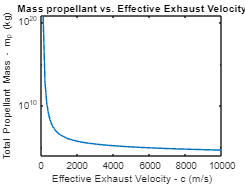

m_p2 = 134000./(c_eff-1.34);


figure(1)
semilogy(c_eff,m_p)
xlabel("Effective Exhaust Velocity - c (m/s)")
ylabel("Total Propellant Mass - m_p (kg)")
xlim([0,10000])
ylim([1e4,max(m_p)])
title("Mass propellant vs. Effective Exhaust Velocity")

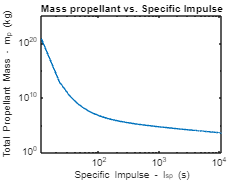



figure(2)
loglog(Isp,m_p)
xlabel("Specific Impulse - I_sp (s)")
ylabel("Total Propellant Mass - m_p (kg)")
title("Mass propellant vs. Specific Impulse")

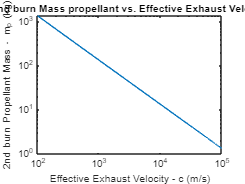




figure(3)
loglog(c_eff,m_p2)
xlabel("Effective Exhaust Velocity - c (m/s)")
ylabel("2nd burn Propellant Mass - m_p (kg)")
% xlim([0,100000])
% ylim([min(m_p),max(m_p)])
title("2nd burn Mass propellant vs. Effective Exhaust Velocity")